# Week 14

12/6

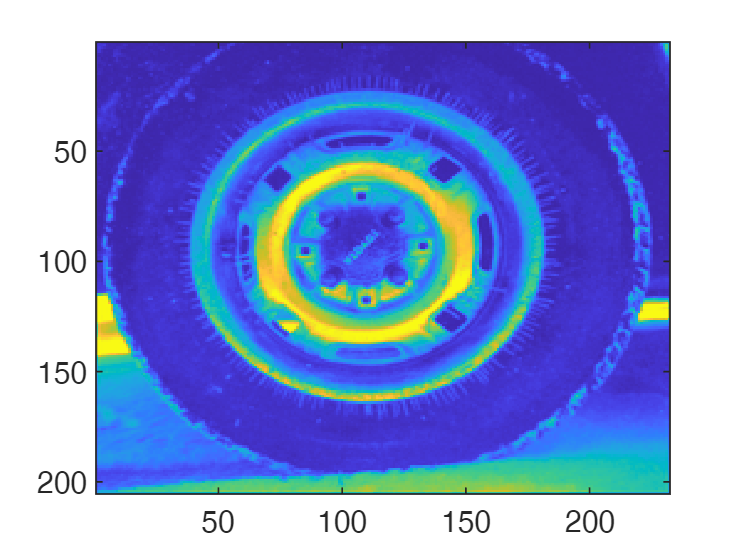

img = imread("tire.tif");
figure; imagesc(img);

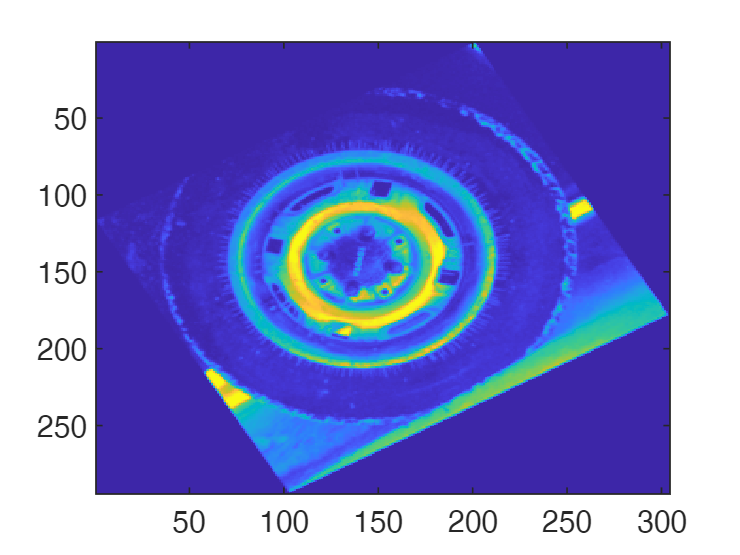

c = cosd(30);
s = sind(30);
trans = maketform('affine', [c -s 0;s c 0; 0 0 1]);
t_img = imtransform(img, trans);
figure; imagesc(t_img);

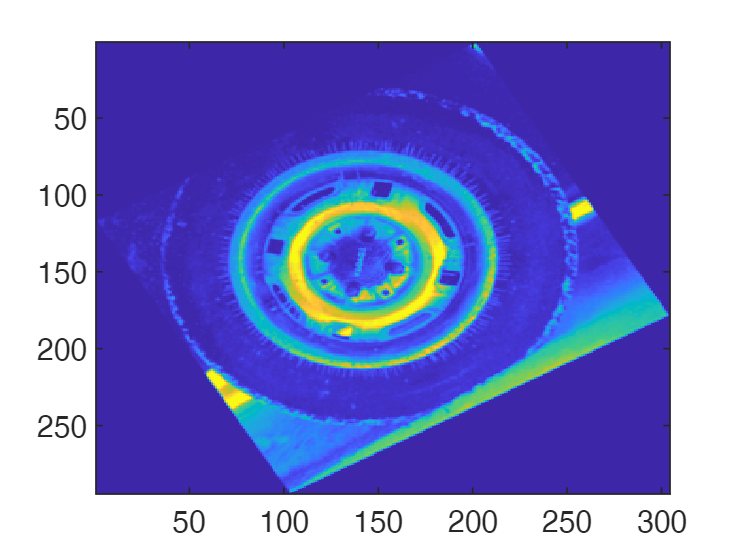


r_img = imrotate(img, 30, "bicubic");
figure; imagesc(r_img);

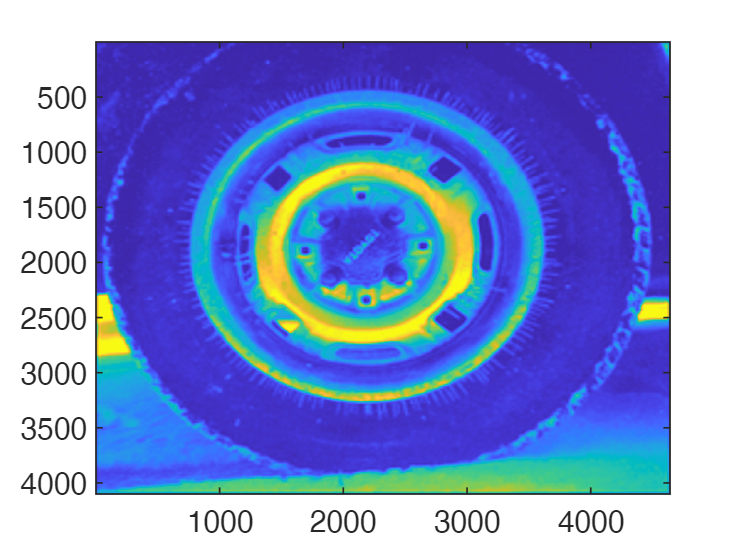


s_img = imresize(img, 20, "bicubic");
figure; imagesc(s_img);

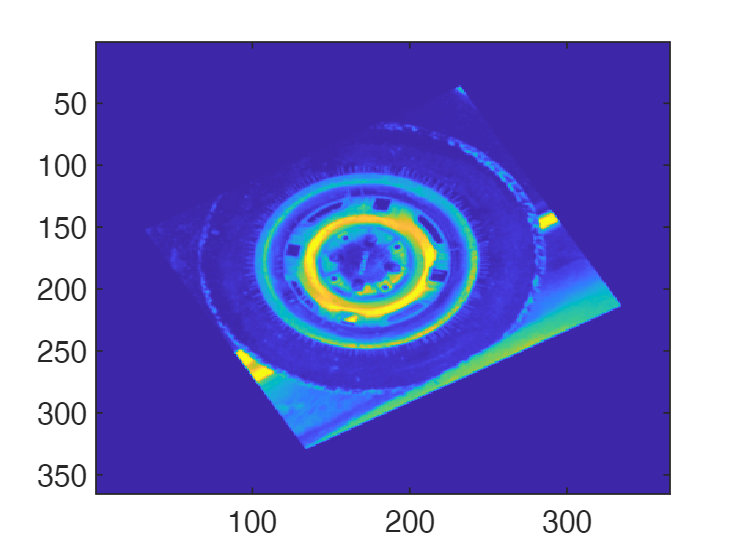


% three shear rotation method
t = tand(30/2);
s1 = maketform('affine', [1 -t 0; 0 1 0; 0 0 1]);
s2 = maketform('affine', [1 0 0; s 1 0; 0 0 1]);

tsr_img = imtransform(imtransform(imtransform(img, s1), s2), s1);
figure; imagesc(tsr_img);